# Calculos por grupo

Este script utiliza el dataset Patients, que contiene 100 observaciones con algunos datos generales y médicos, este data set es parte de Matlab, lo utilizaremos de manera didactica para mostrar ejemplos de las funciones disponibles para exploración, visualización, depuración, normalización, regresión y medidas de calidad que tenemos disponibles

## Configuración inicial

Ejecute el código de esta sección para cargar el dataset en una tabla y convertir las variables de texto en variables categorical. No hay datos faltantes en este dataset

### Carga del dataset y creación de tabla

Además de la presión diastólica y sistólica, las siguientes variables se incluyen para cada paciente:

- age

- gender

- height

- weight

- smoker status

- self-assessed health status

load patients
data = table(Age,Gender,Height,Weight,Smoker,SelfAssessedHealthStatus,Systolic,Diastolic);
clearvars -except data

### Conversión de variables de texto a categorical

Note que Gender es variable categorical simple, mientras que el estado de salud autoevaluado presenta niveles por lo que será llamado categorical ordinal, para indicar que va de menor a mayor la categoría

data.Gender = categorical(data.Gender);
data.SelfAssessedHealthStatus = categorical(data.SelfAssessedHealthStatus,{'Poor','Fair','Good','Excellent'},'Ordinal',true);

### Inspección del dataset

Antes de realizar operaciones por grupo, es importante entender cada variable, de tal manera que sean más fáciles de identificar y comprender diferencias entre los grupos. Ejecute el código en esta sección, después use la tabla para inspeccionar los tipos de dato de cada variable, asi como su rango y distribución

data

data = 100×8 table
    Age    Gender    Height    Weight    Smoker    SelfAssessedHealthStatus    Systolic    Diastolic
    ___    ______    ______    ______    ______    ________________________    ________    _________

    38     Male        71       176      true             Excellent              124          93    
    43     Male        69       163      false            Fair                   109          77    
    38     Female      64       131      false            Good                   125          83    
    40     Female      67       133      false            Fair                   117          75    
    49     Female      64       119      false            Good                   122          80    
 

### Summarize

La función summary nos entregará información sobre la tendencia central junto con máximo y mínimo valor por cada columna, el valor 100x1 indica 100 filas u observaciones y 1 columna

Para las variables categorical, ordinal categorical y logical, entregará la cantidad de observaciones para cada categoria en esa columna

summary(data)

Variables:

    Age: 100×1 double

        Values:

            Min          25   
            Median       39   
            Max          50   

    Gender: 100×1 categorical

        Values:

            Female       53   
            Male         47   

    Height: 100×1 double

        Values:

            Min          60   
            Median       67   
            Max          72   

    Weight: 100×1 double

        Values:

            Min          111  
            Median     142.5  
            Max          202  

    Smoker: 100×1 logical

        Values:

            True        34   
            False       66   

    SelfAssessedHealthStatus: 100×1 ordinal categorical

        Values:

            Poor            11   
            Fair            15   
            Good            40   
            Excellent       34   

    Systolic: 100×1 double

      

## Cálculo de estadística por grupo

Los ejemplos siguientes usan la función `groupsummary` para calcular valores en una o mas variables del grupo

### Calcule la mediana del peso por género

Al inspeccionar las variables, notamos que en algunas variables se observan dos grupos claramente definidos, por ejemplo con la columna Weight. 

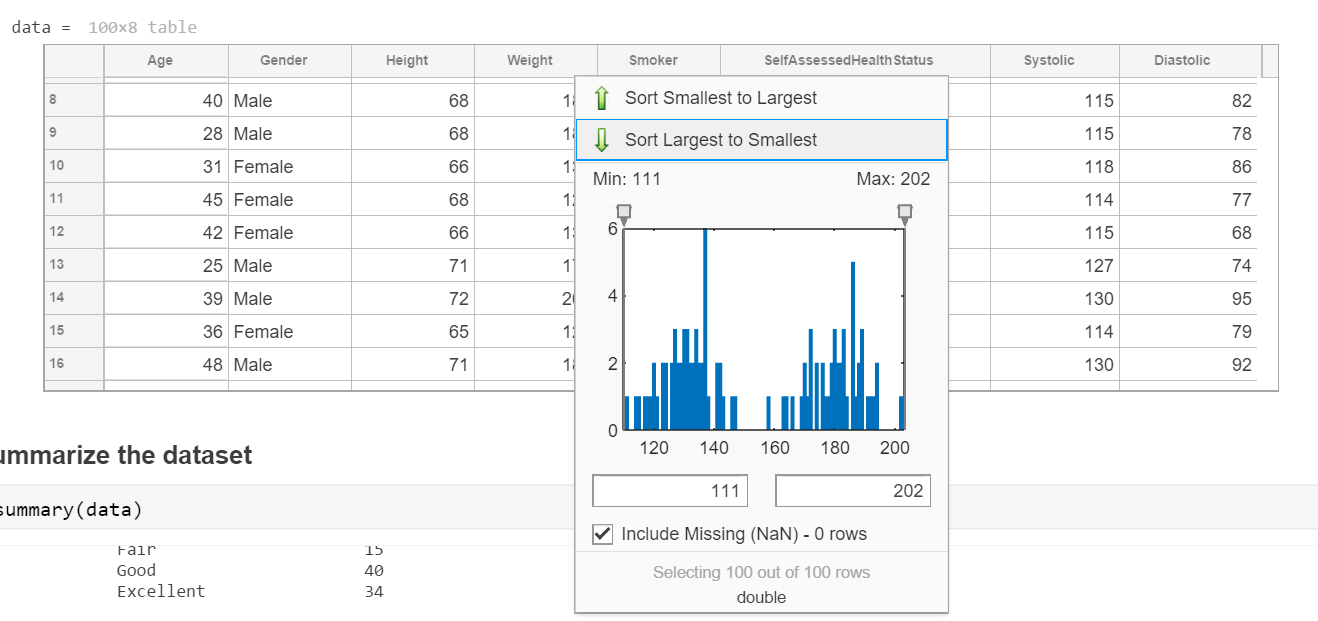

En el caso del peso es una presunción natural, que puede ser verificada obteniendo el valor de la mediana de la variable peso por género en lugar de obtenerla de manera general. Con groupsummary vamos a obtener la mediana del peso, para cafa género en el dataset

groupsummary(data,'Gender','median','Weight')

ans = 2×3 table
    Gender    GroupCount    median_Weight
    ______    __________    _____________

    Female        53             131     
    Male          47             181     


¿Como funciona groupsummary? veamos el archivo de ayuda de matlab [groupsummary help](https://www.mathworks.com/help/matlab/ref/double.groupsummary.html)

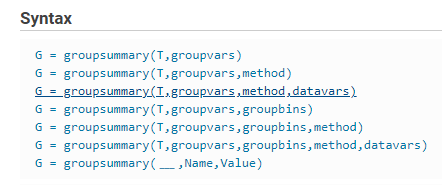 

Estamos utilizando 4 valores de entrada, en el archivo de ayuda viene la descripción y ejemplo para este caso, donde T es nuestra tabla de datos, groupvars, son las variables que vamos a usar para agrupar, solo estamos usando una que es 'Gender', pero podrian ser mas, por ejemplo `[``"HealthStatus"``,``"Smoker"``] entonces obtendriamos la mediana del peso para fumadores y no fumadores de acuerdo a como consideran su estado de salud`

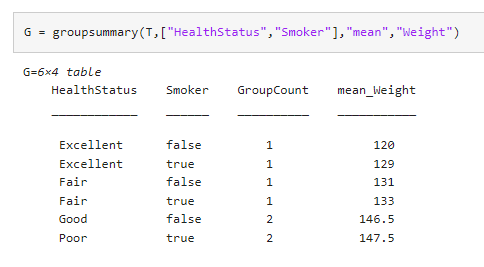

El recer valor es 'median' indica la operación que queremos realizar para cada grupo, los descriptores estadísticos disponibles son: 

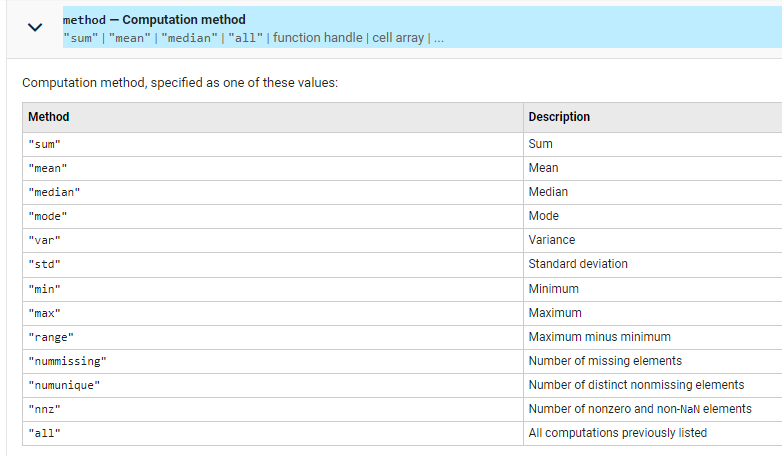

y el último argumento es 'weight' aqui solo elegimos a que columna vamos a aplicar el descriptor que elegimos

Entonces supongamos que queremos una pequeña tabla que nos ponga 4 grupos, fumadores y no fumadores por género, y deseamos obtener el promedio de presión sistólica y diastólica para cada uno de estos grupos

groupsummary(data,["Gender","Smoker"],'mean',{'Systolic','Diastolic'})

ans = 4×5 table
    Gender    Smoker    GroupCount    mean_Systolic    mean_Diastolic
    ______    ______    __________    _____________    ______________

    Female    false         40           119.42             79.05    
    Female    true          13              129            89.231    
    Male      false         26           119.35            79.885    
    Male      true          21           129.57            90.333    


Así la primer fila de esta tabla nos dice, las 40 mujeres no fumadoras de este dataset, en promedio tienen en promedion una presión de 119/79

mientras que la fila 4, los 21 hombres fumadores de este estudio en rpomedio tienen una presión de 129/90.

También podemos deducir que los fumadores, ya sean hombres o mujeres parecen presentar una presión mas alta en promedio

### Calcule el promedio, minimo y maximo peso por género

Como es de esperarse la diferencia entre géneros es clara mostrando la mediana. Note como existen pocos pacientes cerca de la mediana general de los datos (142.5). Para calcular e inspeccionar el promedio, mínimo y máximo valor por género, usamos un código similar al siguiente. Pueden calcularse multiples valores agrupanfo las funciones entre llaves.

groupsummary(data,'Gender',{'min','mean','max'},'Weight')

ans = 2×5 table
    Gender    GroupCount    min_Weight    mean_Weight    max_Weight
    ______    __________    __________    ___________    __________

    Female        53           111          130.47          147    
    Male          47           158          180.53          202    


Los resultados mostrados confirman que las diferencias en la variable Peso entre ambos grupos se deben principalmente a diferencia en el género.

### Calcule el promedio de la presión sistólica y diastólica por fumador

Fumar es una causa de hipertensión, ejecute el código y obtenga el promedio de las presiones agrupados por fumador/no fumador (1=fumador, 0=No fumador)

groupsummary(data,'Smoker','mean',{'Systolic','Diastolic'})

ans = 2×4 table
    Smoker    GroupCount    mean_Systolic    mean_Diastolic
    ______    __________    _____________    ______________

    false         66           119.39            79.379    
    true          34           129.35            89.912    


### Calcule el promedio de la presión diastólica y sistólica por autoevaluación del estado de salud

Los pacientes tienen en claro su estado de salud? Ejecute el código siguiente y analice los resultados

groupsummary(data,'SelfAssessedHealthStatus','mean',{'Systolic','Diastolic'})

ans = 4×4 table
    SelfAssessedHealthStatus    GroupCount    mean_Systolic    mean_Diastolic
    ________________________    __________    _____________    ______________

           Poor                     11           122.45            81.818    
           Fair                     15           120.33            82.867    
           Good                     40              124             83.25    
           Excellent                34           122.53            83.029    


### Calcule el promedio de las personas por estado de salud pero bajo dos grupos

Observamos que la autoevaluación "Good" y "Excellent" tienen presiones mas altas que aquellos autoevaluados mas bajo. Ya que los grupos de algunas categorias on relativamente pequeños, el código siguiente los combina en un solo grupo (0) con aquellos que se autocalifican con un nivel mas alto (1). Es posible utilizar el operador ">" para datos categorial tipo ordinales o que representen una escala

grp = data.SelfAssessedHealthStatus > 'Fair'

grp = 100×1 logical array
   1
   0
   1
   0
   1
   1
   1
   1
   1
   1


Note que este resultado no es una varable dentro de nuestra tabla, y aun así es posible usarlo con los datos de la tabla

groupsummary([data.Systolic,data.Diastolic],grp,'mean')

ans =   121.2308   82.4231
  123.3243   83.1486


La primer fila corresponde a la presión sanguinea para el grupo 0 ("Fair " o "Poor") y el segundo grupo para 1 ("Good" o "Excellent"). Note que la diferencia en el promedio de la presión sanguinea por grupos se mantiene aun con grupos combinados

## Visualizando relaciones grupales    

### Genere un heat-map con las variables self-assessed health y smoker status

En la sección anterior se demostro de una manera contraintuitiva que los estados de salud GOOD o mejores tienen una presión sanguínea mayor en promedio que aquellos calificados mas bajo. Dado que los fumadores presentan mayor presión sanguinea que los no fumadores, una conclusión puede ser que los fumadores con presión alta consideran que su estado de salud es bueno, aumentando la presencia de presiones altas en estos grupos

- Una opción para representar esta pregunta es obtener la proporción de fumadores en cada grupo: 

groupsummary(data,["SelfAssessedHealthStatus","Smoker"])

ans = 8×3 table
    SelfAssessedHealthStatus    Smoker    GroupCount
    ________________________    ______    __________

           Poor                 false          8    
           Poor                 true           3    
           Fair                 false         10    
           Fair                 true           5    
           Good                 false         24    
           Good                 true          16    
           Excellent            false         24    
           Excellent            true          10    


- De manera alternativa, una tabla con la cantidad de fumadores  vs no fumadores mostrada por estado de salud percibido puede ser obtenida utilizando la función [`crosstab`](https://www.mathworks.com/help/stats/crosstab.html). 

crosstab(data.SelfAssessedHealthStatus,data.Smoker)

ans =      8     3
    10     5
    24    16
    24    10


Por último, la misma información desde la tabulación cruzada puede ser generada con heatmap

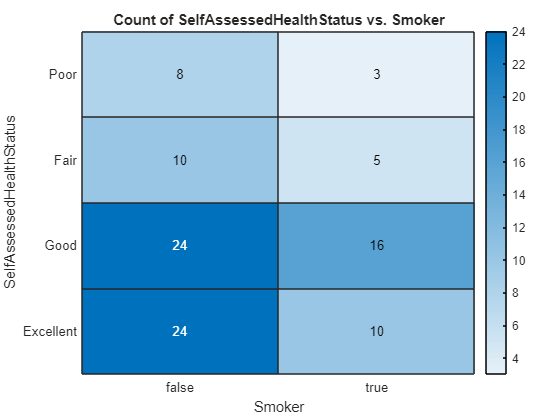

heatmap(data,'Smoker','SelfAssessedHealthStatus');

Heatmaps son especialmente utiles para identificar grupos sobre/bajo representados que pueden introducir sesgo al análisis y producir resultados erroneos. A partir de las ultimas visualizaciones, es mas claro que el grupo con estado de salud autoevaluado como "Good" contiene un alto número de fumadores, el cual representa el grupo con la mayor presión sangüinea en promedio

### Uso de gráfica Scatter para datos agrupados

Estas gráficas pueden ser de utilidad para explorar posibles relaciones entre variables. Sin embargo algunas relaciones pueden aparecer solo para ciertos grupos. Estas diferencias pueden ser dificiles de determinar por la gráfica Scatter por si sola, para estos casos es de utilidad agrupar y graficar. En el código presentado se muestra presión diastólica vs peso agrupado por género

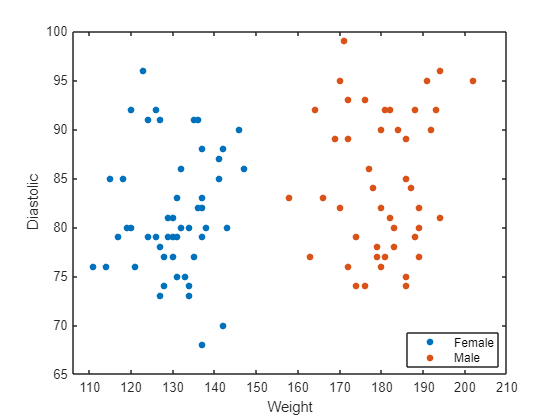

gscatter(data.Weight,data.Diastolic,data.Gender);
xlabel('Weight');
ylabel('Diastolic')

### Generando matriz scatter a partir de grupos

En caso de explorar datos con un número considerable de variables, una gráfica por grupos para múltiples combinaciones se puede generar con la función [`gplotmatrix`](https://www.mathworks.com/help/stats/gplotmatrix.html)`. `Utilice el control interactivo para seleccionar la variable a agrupar y generar la visualización

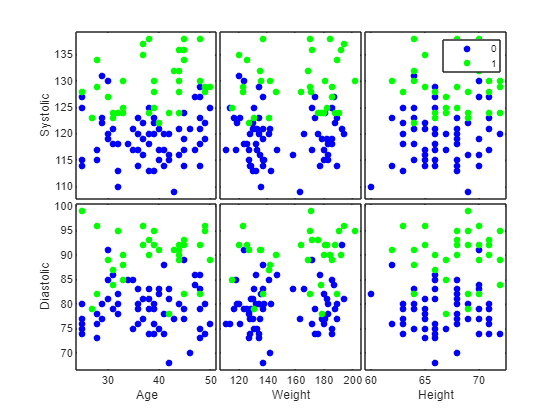

grp = data.Smoker;
gplotmatrix([data.Age,data.Weight,data.Height],[data.Systolic,data.Diastolic],grp,...
    [],[],[],[],[],{'Age','Weight','Height'},{'Systolic','Diastolic'})